% Read in N x N x Time Slice Adj Array
filenames = dir("/mnt/chrastil/lab/users/rob/projects/DynConn/3DArrays/sub-*Coh_2mm_3Darray.mat");
rois = 414;

% Subject 33
i = 3;

sub_label = split(filenames(i).name, "_");
sub_label = split(sub_label(1), "-");
sub_labels(i) = sub_label(2);
disp(filenames(i).name);

arr_dict = load(fullfile(filenames(i).folder, filenames(i).name));

array3D_ex1 = permute(arr_dict.scan_1, [3 2 1]);
array3D_ex2 = permute(arr_dict.scan_2, [3 2 1]);

A = cat(3, array3D_ex1, array3D_ex2);


% Turn Adj Array into Modularity Array
[B, mm] = multiord(A, 1, 1);

PP = @(S) postprocess_ordinal_multilayer(S,T);

% Perform Optimization with Generalized Louvain Method
[S,Q, n_it] = iterated_genlouvain(B, 10000, 0, 1, 'moverandw', [], PP);

Q = Q/mm;
S = reshape(S,N,T);


% Partition significance test
sigs = [];

for time_point = 1:size(S, 2)
    community_partition = S(:, time_point);
    adjArray = array3D(:, :, time_point);
    [sigMatrix, Qmatrix, Qmatrix_r] = sig_permtest(community_partition, adjArray, 1000);
    sigs = [sigs sigMatrix(:)'];
end

proportion_significant = mean(sigs < 0.05);
proportion_significant

[g, o, prop] = parameter_search(1, 1, A)

gammas = (0.97:0.005:1.07);
omegas = (0.8:.1:1.5);

g_range = size(gammas, 2)

g_range = 21

o_range = size(omegas, 2)

o_range = 8

prop_sigs_matrix = zeros([o_range g_range]);

disp("GO");

GO



for g = 1:g_range

    for o = 1:o_range
        gamma = gammas(g)
        omega = omegas(o)
        [gamma, omega, prop] = parameter_search(gamma, omega, A);
        prop_sigs_matrix(o, g) = prop;

    end
end

gamma = 0.9700

omega = 0.8000

gamma = 0.9700

omega = 0.9000

gamma = 0.9700

omega = 1

gamma = 0.9700

omega = 1.1000

gamma = 0.9700

omega = 1.2000

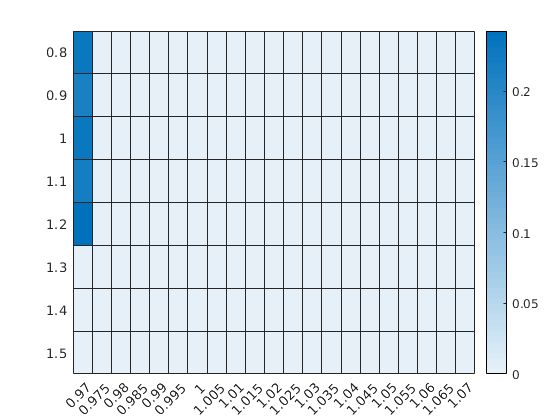

h = heatmap(prop_sigs_matrix);
h.XDisplayLabels = string(gammas);
h.YDisplayLabels = string(omegas);